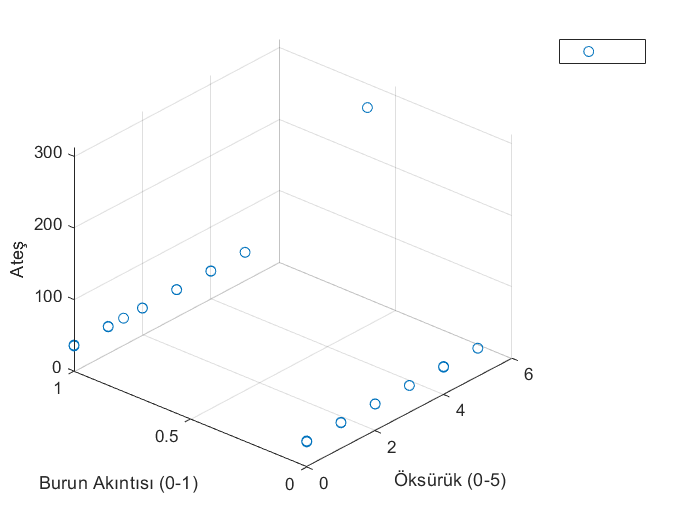

clear all; clc;

%dosya ismi tanımlanır
dosyadi = "param.xlsx";

%bütün değerler okunur
degerler = xlsread(dosyadi);

% dosyaların okunması
[~,txtData1] = xlsread(dosyadi,'F4:F81'); %bu satır ağrı bölgesi değerleri okur mutlaka nan değerleri sil
[~,txtData2] = xlsread(dosyadi,'R4:R81'); %bu satır sektör bilgisini değerleri okur
[~,txtData3] = xlsread(dosyadi,'S4:S81'); %bu satır hastalık değerlerini okur


% string değerleri encode etmek için aşağıdaki code kullanılır kullanmazsan
% sonuçlar yanlış olur şuan için programa yüklü değil.
label_bol = categorical(txtData1);
label_sek = categorical(txtData2);
label_hastalik = categorical(txtData3);

% [R,P] = corrcoef(degerler);
% degerler = degerler()
A = corrcoef(degerler);

oks = degerler(:,6);
bur = degerler(:,2);
ates = degerler(:,3);

ates = sort(ates);
oks = sort(oks);

plot3(oks, bur, ates, 'o')

view([-48.59 33.00])
grid on
legend('show','Location','northeastoutside')
xlabel('Öksürük (0-5)')
ylabel('Burun Akıntısı (0-1)')
zlabel('Ateş')
legend('','Location','northeastoutside')

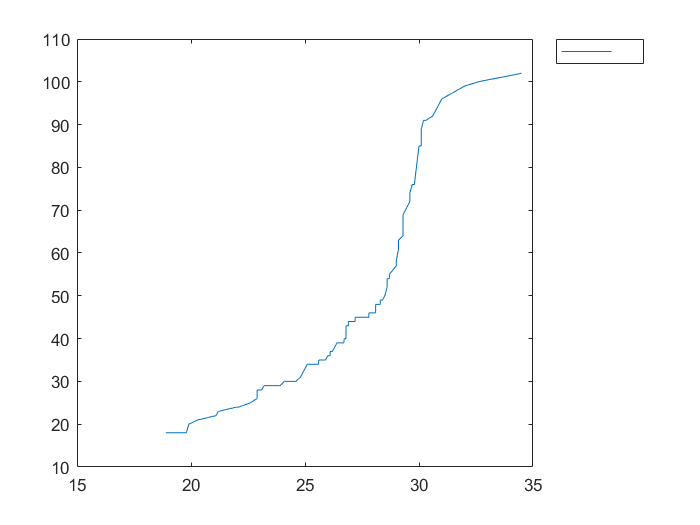

kitle = degerler(:,16);
yas = degerler(:,1);

kitle = sort(kitle);
yas = sort(yas);

plot(kitle,yas)

legend('')

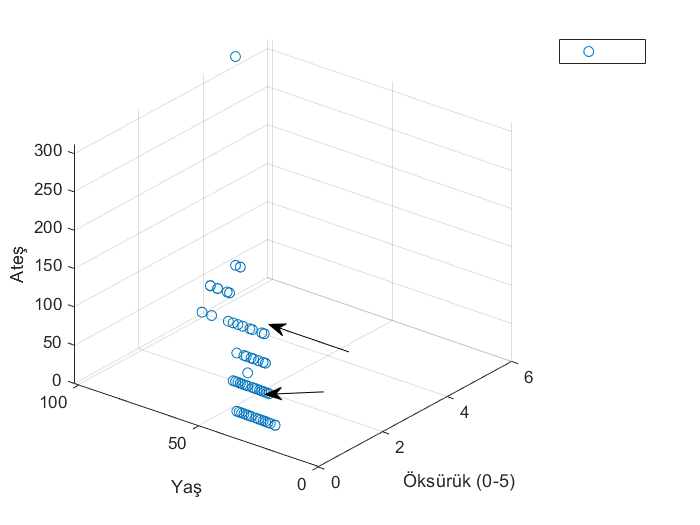

plot3(oks, yas, ates, 'o')

view([-48.59 33.00])
grid on
legend('show','Location','northeastoutside')
xlabel('Öksürük (0-5)')
ylabel('Yaş')
zlabel('Ateş')
legend('','Location','northeastoutside')

view([-51.56 29.39])
annotation('arrow',[0.4983 0.384],[0.3297 0.3821])
annotation('arrow',[0.4625 0.3786],[0.2536 0.2488])

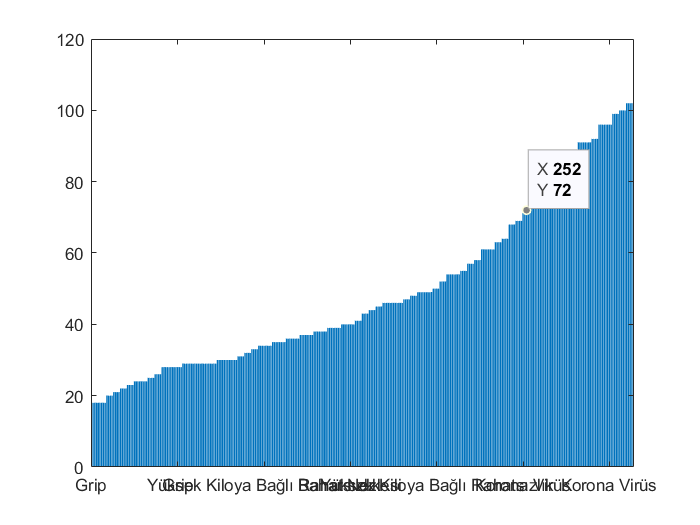

bar(yas)
set(gca,'xticklabel',label_hastalik.')